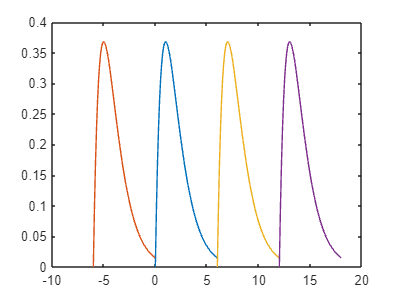

%%Exercicio 01
%sinal x(t) plot
t = 0:0.1:6;
x = t.*exp(-t);
plot(t, x, t-6, x, t+6, x, t+12, x)

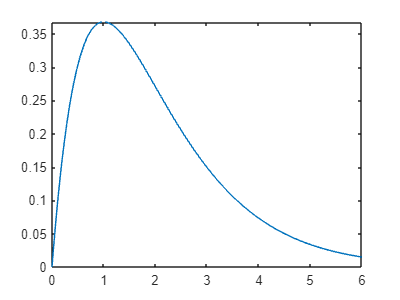

%SF exp complexa
t0 = 0;
T = 6;
w = 2*pi/T;
syms t;
x = t*exp(-t);
fplot(x, [t0 T])

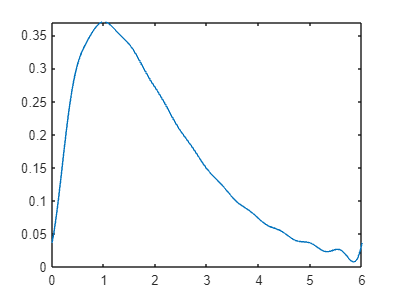


%aproximando utilizando 21 termos 
for k = -10:10
    a(k + 11) = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
end
for k = -10:10
    ex(k + 11) = exp(j*k*w*t);
end
xxe = sum(a.*ex);
fplot(xxe, [t0, t0+T])

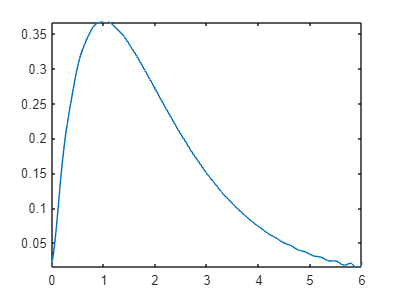

%SF forma trigonometrica
T = 6;
t0 = 0;
w = 2*pi/T;
syms t
x = t*exp(-t);
a0 = (1/T) * int(x, t, t0, t0+T);
for n= 1:20
    b(n) = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
    c(n) = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
end

k = 1:20;
xxt = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t));
fplot(xxt, [t0, t0+T])

%Comparação
t = -6:0.1:18;
xxt = eval(xxt);
xxe = eval(xxe);
plot(t, xxt, t, xxe)

legend("Aproximação por trigonometrica", "Aproximação por Exp")

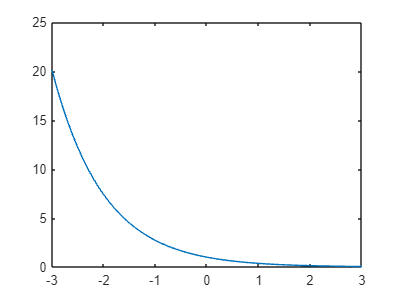

%%Exercicio 02
%sinal 
t = -3:0.1:3;
x = exp(-t);
plot(t, x)

%Forma exp complexa 
clear all
close all
t0 = -3;
T = 6;
w = 2*pi/T;
syms t
x = exp(-t);
fplot(x, [t0 T])
for k = -6:6
    a_exp(k + 7) = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
end
for k = -6:6
    ex(k+7) = exp(j*k*w*t);
end
%{
xx2 = sum(a_exp.*ex);
fplot(xx2, [t0, t0+T])
%}


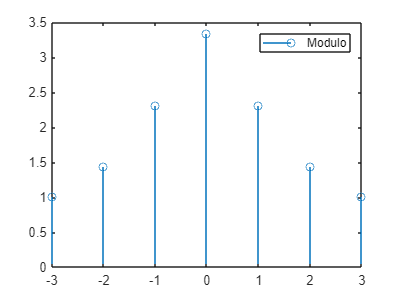

%Representando em fase e modulo
clear all
close all
T = 6;
t0 = -3;
w = 2*pi/T;
syms t k 
x = exp(-t);
a = (1/T) * int(x*exp(-j*k*w*t), t, t0, t0+T);
k1 = -3:3;
a_exp = subs(a, k, k1);
figure
stem(k1, abs(a_exp));
legend("Modulo")

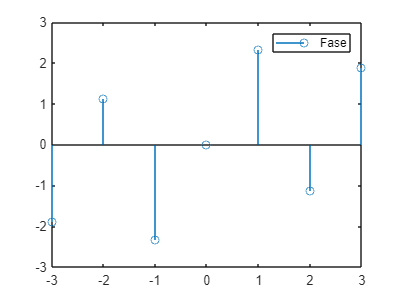

figure 
stem(k1, angle(a_exp))
legend("Fase")

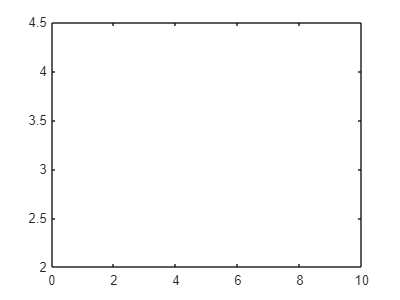

%Forma trigonometrica
clear all
close all
T = 6;
t0 = -3;
w = 2*pi/T;
syms t
x = exp(-t);

a0_t = (1/T) * int(x, t, t0, t0+T);

for n = 1:10
    b_t(n) = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
    c_t(n) = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
end
n = 1:10;
plot(n, a0_t)

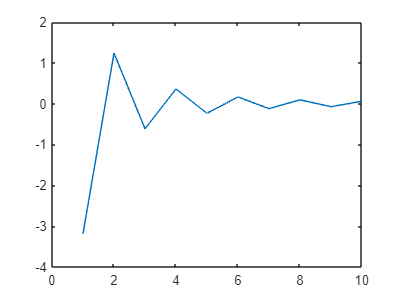

plot(n, b_t)

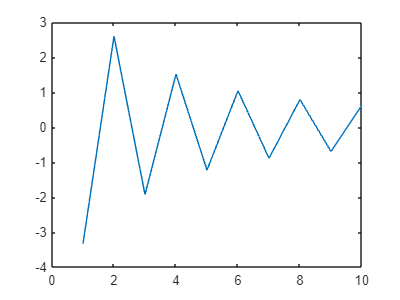

plot(n, c_t)

%Forma trigonometrica compacta
clear all
close all
T = 6;
t0 = -3;
w = 2*pi/T;
syms t n
x = exp(-t);

a0_tc = 1/T * int(x, t, t0, t0+T);
b = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
c = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);
n1 = 0:10;
b_tc = subs(b, n, n1);
c_tc = subs(c, n, n1);

Ac = sqrt(b_tc.^2+c_tc.^2);
thetac = atan2(-c_tc, b_tc);